# Experiment No. 5

# Bit error rate of 16 bit Quadrature Amplitude Modulation

# (16- QAM) with and without Gray labelling

## Communications Lab

## *190020039*

### Initialize Matlab

close all;
clear;
clc;

### Declaring some variables

% SNR array varying in the range of -10 to +10 dB in steps of 1 dB
snrdb=-10:10;

### Message signal (bits)

% no of bits in mesaage array
nbits=50000;
% message bit array
m=randi([0,1],nbits,1);

### 16 QAM Modulation (with Gray labelling)

% generate 16 QAM constellation as complex numbers
con = [+1+1i +3+1i +1+3i +3+3i ...
       -1+1i -3+1i -1+3i -3+3i ...
       -1-1i -3-1i -1-3i -3-3i ...
       +1-1i +3-1i +1-3i +3-3i];
% avg energy of constellation
avgE=mean(abs(con).^2);
% modulating message signal array
% 0000 mapped to -3+3i; 0001 mapped to -3+1i
% 0010 mapped to -3-3i; 0011 mapped to -3-1i
% 0100 mapped to -1+3i; 0101 mapped to -1+1i
% 0110 mapped to -1-3i; 0111 mapped to -1-1i
% 1000 mapped to +3+3i; 1001 mapped to +3+1i
% 1010 mapped to +3-3i; 1011 mapped to +3-1i
% 1100 mapped to +1+3i; 1101 mapped to +1+1i
% 1110 mapped to +1-3i; 1111 mapped to +1-1i
% reshaping message and storing 4 bits in each row
m_reshape=reshape(m,4,[])';
% temporary variable used for mapping
m2=1000*m_reshape(:,1)+100*m_reshape(:,2)+10*m_reshape(:,3)+m_reshape(:,4);
% modulated signal array
mod=(m2==0)*(-3+3i)+(m2==1)*(-3+1i)+(m2==10)*(-3-3i)+(m2==11)*(-3-1i)+...
    (m2==100)*(-1+3i)+(m2==101)*(-1+1i)+(m2==110)*(-1-3i)+(m2==111)*(-1-1i)+...
    (m2==1000)*(3+3i)+(m2==1001)*(3+1i)+(m2==1010)*(3-3i)+(m2==1011)*(3-1i)+...
    (m2==1100)*(1+3i)+(m2==1101)*(1+1i)+(m2==1110)*(1-3i)+(m2==1111)*(1-1i);
mod=mod/sqrt(avgE); % normalizing to get avg energy as 1

### Adding AWGN and Demodulating (with Gray labelling)

% declaring estimated Bit Error Rate (BER) array
ber_est = zeros(length(snrdb),1);
for k=1:length(snrdb)
% calculating sigma from noise power
sigma=sqrt(1/(8*(10^(snrdb(k)/10))));
% adding AWGN to modulated signal
received = mod + sigma*randn(nbits/4,1)+1i*sigma*randn(nbits/4,1);
% renormalizing the received array with avg energy
received=received*sqrt(avgE);
% DECLARING 2 ARRAYS USEFUL FOR ERROR CALCULATION
% creating array of  size (nbits/4,16) with 
% each row as constellation array
arr1=ones(nbits/4,16).*con;
% creating array size (nbits/4,16) with 
% each column as received signal array
arr2=ones(nbits/4,16).*received;
% finding distance between 
% constellation points and received signal
% idx stores index (1, 2, 3,... 16) of min of row of distance array
[dist,idx]=min(abs(arr1-arr2),[],2);
% DEMODULATION
% using index to get demodulated signal bit array 
% idx= 1 is bit=1101; idx= 2 is bit=1001
% idx= 3 is bit=1100; idx= 4 is bit=1000
% idx= 5 is bit=0101; idx= 6 is bit=0001
% idx= 7 is bit=0100; idx= 8 is bit=0000
% idx= 9 is bit=0111; idx=10 is bit=0011
% idx=11 is bit=0110; idx=12 is bit=0010
% idx=13 is bit=1111; idx=14 is bit=1011
% idx=15 is bit=1110; idx=16 is bit=1010
demod=zeros(nbits,1);
for i=1:length(idx)
    if idx(i)==1
        demod(4*i-3:4*i)=[1 1 0 1];
    elseif idx(i)==2
        demod(4*i-3:4*i)=[1 0 0 1];
    elseif idx(i)==3
        demod(4*i-3:4*i)=[1 1 0 0];
    elseif idx(i)==4
        demod(4*i-3:4*i)=[1 0 0 0];
    elseif idx(i)==5
        demod(4*i-3:4*i)=[0 1 0 1];
    elseif idx(i)==6
        demod(4*i-3:4*i)=[0 0 0 1];
    elseif idx(i)==7
        demod(4*i-3:4*i)=[0 1 0 0];
    elseif idx(i)==8
        demod(4*i-3:4*i)=[0 0 0 0];
    elseif idx(i)==9
        demod(4*i-3:4*i)=[0 1 1 1];
    elseif idx(i)==10
        demod(4*i-3:4*i)=[0 0 1 1];
    elseif idx(i)==11
        demod(4*i-3:4*i)=[0 1 1 0];
    elseif idx(i)==12
        demod(4*i-3:4*i)=[0 0 1 0];
    elseif idx(i)==13
        demod(4*i-3:4*i)=[1 1 1 1];
    elseif idx(i)==14
        demod(4*i-3:4*i)=[1 0 1 1];
    elseif idx(i)==15
        demod(4*i-3:4*i)=[1 1 1 0];
    elseif idx(i)==16
        demod(4*i-3:4*i)=[1 0 1 0];
    end
end
% comparing demodulated and message bit array
% calculating Bit Error Rate for each SNR
ber_est(k)=sum(demod~=m)/nbits;
end

### Plotting Graphs (with Gray labelling)

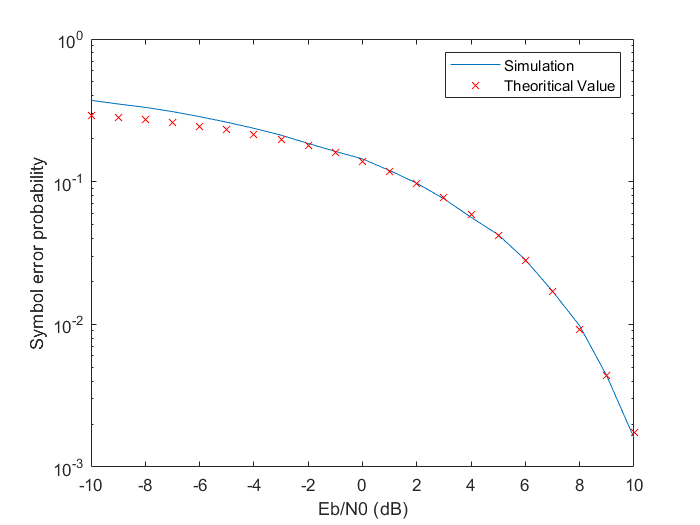

semilogy(snrdb,ber_est); % plotting error from simulation
hold on;
%COMPARE WITH THEORETICAL VALUES USING EQUATION BASED ON Q-Func
snro = 10.^(snrdb/10); % raw SNR values
perr_th = 3/4*qfunc(sqrt(4/5*snro)); % theoretical error
semilogy(snrdb,perr_th,'xr'); % plotting theoretical error
xlabel('Eb/N0 (dB)');
ylabel('Symbol error probability');
legend('Simulation','Theoritical Value','Location','NorthEast');
hold off;

### 16 QAM Modulation (without Gray labelling)

% generate 16 QAM constellation as complex numbers
con = [+1+1i +3+1i +1+3i +3+3i ...
       -1+1i -3+1i -1+3i -3+3i ...
       -1-1i -3-1i -1-3i -3-3i ...
       +1-1i +3-1i +1-3i +3-3i];
% avg energy of constellation
avgE=mean(abs(con).^2);
% modulating message signal array
% 0000 mapped to +1+1i; 0001 mapped to +3+1i
% 0010 mapped to +3+3i; 0011 mapped to +1+3i
% 0100 mapped to -1+1i; 0101 mapped to -3+1i
% 0110 mapped to -3+3i; 0111 mapped to -1+3i
% 1000 mapped to -1-1i; 1001 mapped to -3-1i
% 1010 mapped to -3-3i; 1011 mapped to -1-3i
% 1100 mapped to +1-1i; 1101 mapped to +3-1i
% 1110 mapped to +3-3i; 1111 mapped to +1-3i
% reshaping message and storing 4 bits in each row
m_reshape=reshape(m,4,[])';
% temporary variable used for mapping
m2=1000*m_reshape(:,1)+100*m_reshape(:,2)+10*m_reshape(:,3)+m_reshape(:,4);
% modulated signal array
mod=(m2==0)*(1+1i)+(m2==1)*(3+1i)+(m2==10)*(3+3i)+(m2==11)*(1+3i)+...
    (m2==100)*(-1+1i)+(m2==101)*(-3+1i)+(m2==110)*(-3+3i)+(m2==111)*(-1+3i)+...
    (m2==1000)*(-1-1i)+(m2==1001)*(-3-1i)+(m2==1010)*(-3-3i)+(m2==1011)*(-1-3i)+...
    (m2==1100)*(1-1i)+(m2==1101)*(3-1i)+(m2==1110)*(3-3i)+(m2==1111)*(1-3i);
mod=mod/sqrt(avgE); % normalizing to get avg energy as 1

### Adding AWGN and Demodulating (with Gray labelling)

% declaring estimated Bit Error Rate (BER) array
ber_est = zeros(length(snrdb),1);
for k=1:length(snrdb)
% calculating sigma from noise power
sigma=sqrt(1/(8*(10^(snrdb(k)/10))));
% adding AWGN to modulated signal
received = mod + sigma*randn(nbits/4,1)+1i*sigma*randn(nbits/4,1);
% renormalizing the received array with avg signal energy
received=received*sqrt(avgE);
% DECLARING 2 ARRAYS USEFUL FOR ERROR CALCULATION
% creating array of  size (nbits/4,16) with 
% each row as constellation array
arr1=ones(nbits/4,16).*con;
% creating array size (nbits/4,16) with 
% each column as received signal array
arr2=ones(nbits/4,16).*received;
% finding distance between 
% constellation points and received signal
% idx stores index (1, 2, 3,... 16) of min of row of distance array
[dist,idx]=min(abs(arr1-arr2),[],2);
% DEMODULATION
% using index to get demodulated signal bit array 
% idx= 1 is bit=0000; idx= 2 is bit=0001
% idx= 3 is bit=0011; idx= 4 is bit=0010
% idx= 5 is bit=0100; idx= 6 is bit=0101
% idx= 7 is bit=0111; idx= 8 is bit=0110
% idx= 9 is bit=1000; idx=10 is bit=1001
% idx=11 is bit=1011; idx=12 is bit=1010
% idx=13 is bit=1100; idx=14 is bit=1101
% idx=15 is bit=1111; idx=16 is bit=1110
demod=zeros(nbits,1);
for i=1:length(idx)
    if idx(i)==1
        demod(4*i-3:4*i)=[0 0 0 0];
    elseif idx(i)==2
        demod(4*i-3:4*i)=[0 0 0 1];
    elseif idx(i)==3
        demod(4*i-3:4*i)=[0 0 1 1];
    elseif idx(i)==4
        demod(4*i-3:4*i)=[0 0 1 0];
    elseif idx(i)==5
        demod(4*i-3:4*i)=[0 1 0 0];
    elseif idx(i)==6
        demod(4*i-3:4*i)=[0 1 0 1];
    elseif idx(i)==7
        demod(4*i-3:4*i)=[0 1 1 1];
    elseif idx(i)==8
        demod(4*i-3:4*i)=[0 1 1 0];
    elseif idx(i)==9
        demod(4*i-3:4*i)=[1 0 0 0];
    elseif idx(i)==10
        demod(4*i-3:4*i)=[1 0 0 1];
    elseif idx(i)==11
        demod(4*i-3:4*i)=[1 0 1 1];
    elseif idx(i)==12
        demod(4*i-3:4*i)=[1 0 1 0];
    elseif idx(i)==13
        demod(4*i-3:4*i)=[1 1 0 0];
    elseif idx(i)==14
        demod(4*i-3:4*i)=[1 1 0 1];
    elseif idx(i)==15
        demod(4*i-3:4*i)=[1 1 1 1];
    elseif idx(i)==16
        demod(4*i-3:4*i)=[1 1 1 0];
    end
end
% comparing demodulated and message bit array
% calculating Bit Error Rate for each SNR
ber_est(k)=sum(demod~=m)/nbits;
end

### Plotting Graphs (with Gray labelling)

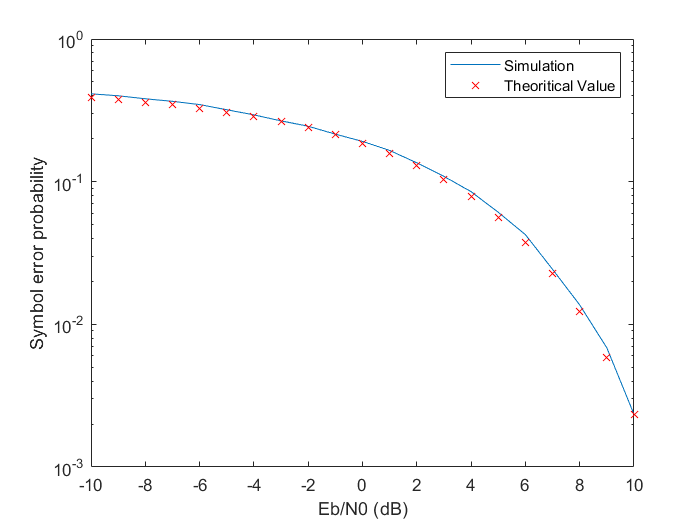

semilogy(snrdb,ber_est); % plotting error from simulation
hold on;
%COMPARE WITH THEORETICAL VALUES USING EQUATION BASED ON Q-Func
snro = 10.^(snrdb/10); % raw SNR values
perr_th = qfunc(sqrt(4/5*snro)); % theoretical error
semilogy(snrdb,perr_th,'xr'); % plotting theoretical error
xlabel('Eb/N0 (dB)');
ylabel('Symbol error probability');
legend('Simulation','Theoritical Value','Location','NorthEast');
hold off;